## Classification with Decision Trees (22/02/2021)

Week 4 of the Intro to Data Science module looks at classification, and in particular the use of decision trees to reach a classification outcome.

Classification is concerned with the allocation of a label to a given set of features. This achieved through a function or mapping from feature or inputs to the label or output, with decision trees being one such method.

Decision trees are a form of classifier that operate through top-down induction, recursively splitting into more branches until a desired level is met. Each of these splits is performed to maximise "purity" measure in the labels, e.g. reducing variance, with "better" splits performed earlier, and hence appearing higher in the decision tree.

This process of splitting can theoretically go on forever, however there is a tradeoff to be established. More splits leads to greater accuracy (on the training set), however reduced generalisation capacity. To this end, a smaller decision tree may perform better than a very large tree, as it will likely have overfit to anomalous data points, which in turn cause wrongful predictions.

As far as evaluating the performance of our classifier, we can do this using metrics such as accuracy, recall, precision and specificity, which can all be readily calculated from a confusion matrix.

We can explore the application of decision trees with a practical worked example, and in this instance, we will return to the Titanic dataset. The most obvious question in this context is whether we can predict if a given passenger will die or survive, or rather, whether we can design a classifier (decision tree) which is capable of assigning the correct class label to a given passenger feature vector to a required level of performance.

We begin by importing and visualising a sample of our data.

data = readtable("./data/titanic.csv");

head(data,5)

ans = 5×8 table
    Survived    Pclass                             Name                                Sex        Age    Siblings_SpousesAboard    Parents_ChildrenAboard     Fare 
    ________    ______    ______________________________________________________    __________    ___    ______________________    ______________________    ______

       0          3       {'Mr. Owen Harris Braund'                            }    {'male'  }    22               1                         0                 7.25
       1          1       {'Mrs. John Bradley (Florence Briggs Thayer) Cumings'}    {'female'}    38               1                         0               71.283
       1          3       {'Miss. Laina Heikkinen'     

Looking at our data, we have several columns to consider. The "Survived" column is our choice of label or class, denoting the outcome of the classification process. Name likely has no relevance, and so we can choose to drop the column at this stage. The remaining columns could all be useful in determining passenger survival, so we will keep these.

Note: we will need to encode sex as numerical values, and in some instances it may be preferable to engage in further feature engineering, perhaps introducing other contextual or supporting information, or combining features to assist the classification process.

% Drop name column
data.Name = [];

% Encode the sex
data.Sex = grp2idx(data.Sex);

% Split into labels and features
labels = data.Survived;
features = data(:,2:end);

First of all, lets split our data into a training and testing set, so we can separately train and evaluate our classifier. Here, we'll use a 70/30 split.

% Create a vector of random numbers for splitting dataset
r = rand(length(labels),1);

% Assign indices to either data split depending on number
train = find(r < 0.7);
test = find(r >= 0.7);

% Assign the data points (labels, features) to corresponding split
train_labels = labels(train);
test_labels = labels(test);
train_features = features(train, :);
test_features = features(test, :);

Now let's train a decision tree on our data.

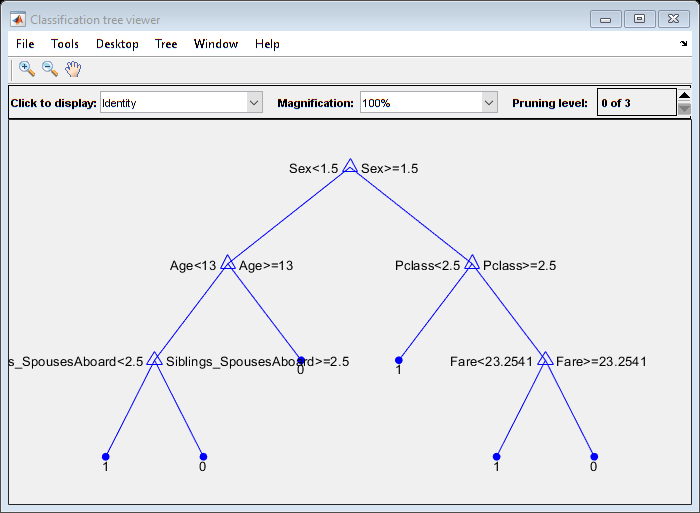

% No of splits
k = 5;

% Fit the classification tree (and visualise)
t = fitctree(train_features, train_labels, "MaxNumSplits", k);
view(t, "Mode", "Graph");

The visualisation above shows the decision tree that resulted from the fitting process. We specified a maximum of 5 branches, which can be seen by counting the number of nodes from which new branches emerge (and where a decision or logical comparison is computed). The decision tree is constructed hierarchically, with the root node having the greatest ability to segment the remaining data into two separable classes, which continues hierarchically throughout the tree. The decision tree is inherently explainable and interpretable, with each branch being interpreted as a logical comparison or thresholding statement - this is not true for all classification models, especially those using deep learning!

In the example above, we used 5 branches, but there is no reason for this limit. We could compute 887 branches, with a different branch per label, however this would be overfitting the model and generally result in poor generalisability, and poor test set performance, as we shall examine later.

% Make predictions
predictions = predict(t, test_features)

predictions =      1
     0
     1
     0
     1
     1
     0
     0
     0
     0


Our predictions are simply a class label, which can be compared with the actual labels to indicate the accuracy of our classifier. The decision tree has essentially created a function to map the feature space to a class label, thereby achieving a classification outcome. A confusion matrix can help us visualise how well this classification objective is met.

%Show confusion matrix
c = confusionmat(test_labels, predictions)

c =    141    16
    32    69


The confusion matrix shown the number of true positives, false positives, false negatives, and true negatives going from top to bottom and left to right. A higher leading diagonal indicates better accuracy (more things classified correctly), while a higher off-diagonal indicates poorer performance (more incorrect classifications).

We can proceed to calculate a set of metrics to quantify the performance of the decision tree.

TP = c(1); % True Positives
FN = c(2); % False Negatives
FP = c(3); % False Positives
TN = c(4); % True Negatives

% Accuracy = (TP + TN) / (P + N)
accuracy = (TP + TN) / (TP + TN + FP + FN)

accuracy = 0.8140

% Recall = Sensitivity = TP / P
recall = TP / (TP + FN)

recall = 0.8150

% Precision = TP / (TP + FP)
precision = TP / (TP + FP)

precision = 0.8981

% Specificity = TN / (TN + FP)
specificity = TN / (TN + FP)

specificity = 0.8118

We can also investigate the effect of overfitting (and more generally, the effect of different decision tree sizes) by comparing the accuracy of our decision tree with varying tree size across both the training and test datasets.

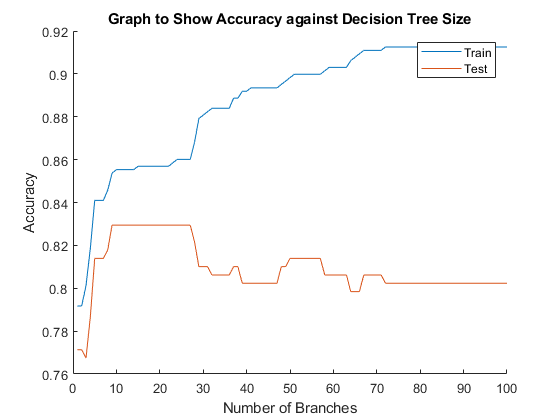

MAX_BRANCHES = 100;
accuracies_train = zeros(MAX_BRANCHES,1);
accuracies_test = zeros(MAX_BRANCHES,1);
for k = 1:MAX_BRANCHES
    % Fit the classification decision tree
    t = fitctree(train_features, train_labels, "MaxNumSplits", k);
    
    % Evaluate on training set
    predictions_train = predict(t, train_features);
    c_train = confusionmat(train_labels, predictions_train);
    accuracy_train = sum(diag(c_train))/sum(sum(c_train));
    accuracies_train(k) = accuracy_train;
    
    % Evaluate on testing set
    predictions_test = predict(t, test_features);
    c_test = confusionmat(test_labels, predictions_test);
    accuracy_test = sum(diag(c_test))/sum(sum(c_test));
    accuracies_test(k) = accuracy_test;
end

% Plot the graph to compare
hold on;
plot(accuracies_train, "DisplayName", "Train");
plot(accuracies_test, "DisplayName", "Test");
legend();
xlabel("Number of Branches");
ylabel("Accuracy");
title("Graph to Show Accuracy against Decision Tree Size");
hold off;

As can be seen from the plot, as the number of branches increases, the training set accuracy continuous to increase monotonically up to theoretically 100% accuracy, where you may have an individual branch or leaf for each and every data point. However, this continual increase is not also present for the training set accuracy, increasing up to around 10 branches, after which it subsequently decreases, due to reduced generalisability (i.e. overfitting).